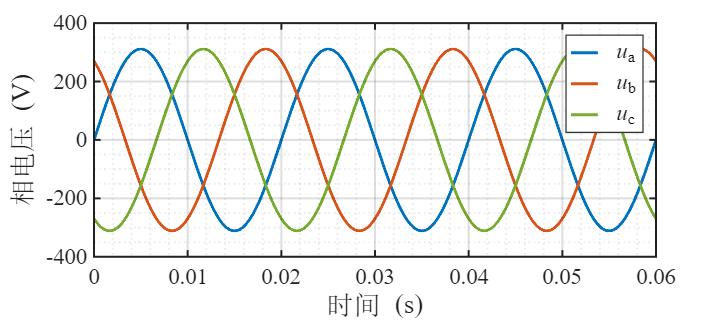

%% 三相电压时域波形绘制（论文级统一风格）
clear; clc; close all;

%% ---------------- Global style（与之前完全一致） ----------------
set(groot, 'defaultFigureColor', 'w');

set(groot, 'defaultAxesFontName', 'Times New Roman');
set(groot, 'defaultTextFontName', 'Times New Roman');

set(groot, 'defaultAxesFontSize', 14);      % 顶刊：刻度字体放大
set(groot, 'defaultAxesLineWidth', 1.2);
set(groot, 'defaultLineLineWidth', 1.8);
set(groot, 'defaultAxesBox', 'on');
set(groot, 'defaultAxesTickDir', 'out');

set(groot, 'defaultAxesTickLabelInterpreter', 'tex');
set(groot, 'defaultTextInterpreter', 'tex');
set(groot, 'defaultLegendInterpreter', 'tex');

%% ---------------- 参数定义 ----------------
Um = 220*sqrt(2);        % 相电压幅值 (V)
omega = 100*pi;         % 角频率 (rad/s)

t = linspace(0, 0.06, 2500);  % 时间轴（3个周期）

%% ---------------- 三相电压 ----------------
ua = Um * sin(omega*t);
ub = Um * sin(omega*t + 2*pi/3);
uc = Um * sin(omega*t + 4*pi/3);

%% ---------------- 颜色（色盲友好 / 印刷友好） ----------------
C1 = [0.00, 0.45, 0.74];   % blue
C2 = [0.85, 0.33, 0.10];   % orange
C3 = [0.47, 0.67, 0.19];   % green

%% ---------------- 绘图 ----------------
fig = figure('Units','centimeters','Position',[3 3 18 8]);  % 单栏/双栏自适应
ax = axes(fig); hold(ax,'on');

plot(t, ua, 'Color', C1);
plot(t, ub, 'Color', C2);
plot(t, uc, 'Color', C3);

grid on; grid minor;

xlim([0 0.06]);
ylim([-400 400]);

%% ---------------- 坐标轴标签（中英混排） ----------------
xlabel('\fontname{SimSun}时间\fontname{Times New Roman} (s)', ...
       'FontSize',16);

ylabel('\fontname{SimSun}相电压\fontname{Times New Roman} (V)', ...
       'FontSize',16);

%% ---------------- 图例（数学斜体 + 下标） ----------------
leg = legend({'{\it u}_a','{\it u}_b','{\it u}_c'}, ...
    'Location','northeast');

set(leg, ...
    'FontName','Times New Roman', ...
    'FontSize',14, ...
    'Box','on', ...
    'EdgeColor',[0.2 0.2 0.2], ...
    'LineWidth',0.8, ...
    'Color','white', ...
    'TextColor','black', ...
    'ItemTokenSize',[16 10]);

%% ---------------- 网格透明度（期刊风格） ----------------
ax.GridAlpha      = 0.15;
ax.MinorGridAlpha = 0.08;
ax.Layer          = 'top';

%% ---------------- 高质量导出 ----------------
% 推荐：矢量 PDF（顶刊最稳）
% exportgraphics(fig,'ThreePhaseVoltage_TimeDomain.pdf','ContentType','vector');

% PNG（600 dpi，投稿系统兼容）
print(fig,'ThreePhaseVoltage_TimeDomain_Journal','-dpng','-r600');